# **A Semi-Automated Script to Quantify Vascular Calcificaiton using 18NaF PET/CT**: **Mapping to a common vascular atlas**



%Copyright (c) 2024 Aaron Sheppard

%Permission is hereby granted, free of charge, to any person obtaining a copy
%of this software and associated documentation files (the "Software"), to deal
%in the Software without restriction, including without limitation the rights
%to use, copy, modify, merge, publish, distribute, sublicense, and/or sell
%copies of the Software, and to permit persons to whom the Software is
%furnished to do so, subject to the following conditions:

%The above copyright notice and this permission notice shall be included in all
%copies or substantial portions of the Software.

%THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR
%IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,
%FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE
%AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER
%LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,
%OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE
%SOFTWARE.


clear all

## User Inputs

Input Slice Width:

voxelvolume = 1*1*1.5;
%SliceWidth = 3.75; %Input the Slice Width of the CT scan
BackgroundSUV = 1.1;%Input the Mean SUV from a ROI drawn in the SVC lumen


## Load in Table and Separate CT and PET data

RawData = readtable("...");
VascularData = unique(RawData,"rows","stable");
%Adjust PET values by dividing by background (TBR)
VascularData.SUV = (VascularData.SUV/BackgroundSUV);

%Separate voxel values into tables specific for HU or SUV (Density suragate and
%PET activity)
VascularCT = VascularData(:,3:6);
VascularCT = sortrows(VascularCT,"VoxelZ","ascend");

VascularPET = VascularData(:,[3:5 7]);
VascularPET = sortrows(VascularPET,"VoxelZ","ascend");

Input Atlas Dimensions (Population Average Length of Vascular Segment):

% These are the scaling factors for the different vascular segments.
    % these were determined by measuring the average length (in mm) for
    % cohort's vascular segments. Technically, the standardized vascular
    % atlas dimensions is in units of mm.

%ToAtlasAorticArch = 175;%Enter the Average Length of Aortic arch and Descending Aorta
SFAscend = 50;
SFDescend = 60;
SFAbdominal = 180 ;%/ SliceWidth; %Enter Average Length of Abdominal Aorta
SFIliac = 165 ;%/ SliceWidth; %Enter Average Length of Iliac Arteries
SFFemoral = 300 ;%/ SliceWidth; %Enter Average Length of Femoral Arteries
SFPop = 80 ;%/ SliceWidth; %Enter Average Length of Popliteal Arteries
%ToAtlasPostTib = 330;% / SliceWidth; %Enter Average Length of Posterial Tibial Arteries

**Input Slice #s Used to Differentiate Vascular Segments:**

% These are the slice positions within MIM
ArchBegin = 241; %Input the Slice Number where Aortic Root begins
AbdominalBegin = 284; %Input the Slicer Number where the Abdominal Aorta Begins
IliacBegin = 401; %Input the Slicer Number where the Iliac Arteries Begin
FemoralBegin = 491; %Input the Slicer Number where the Femoral Arteries Begin
PopBegin = 723; %Input the Slicer Number where the Popliteal Arteries Begin
PostTibBegin = 793; %Input the Slicer Number where the Posterial Tibial Arteries Begin
ending = numel(VascularCT.VoxelX);

## Find point of inflection where descending aorta begins...

% Split voxel data into everything from arch to abdominal aorta 
    % This is to create 3D model of the aortic arch:

idxAbd = VascularData{:,"VoxelZ"} >= AbdominalBegin;
ForSkelData = VascularData(~idxAbd,:);
sampledata = ForSkelData; % rename voxel data for following code
xyzLabels = {'VoxelX', 'VoxelY', 'VoxelZ'};
channels = {'HU','SUV'};
xcol = find(string(sampledata.Properties.VariableNames) == xyzLabels(1));
        % since matlab indeces start at 1, min values are min-1
        xmin = min(sampledata{:,xcol}) -1;
        xrange = max(sampledata{:,xcol}) - xmin;
        xmargin = 8;
        
        ycol = find(string(sampledata.Properties.VariableNames) == xyzLabels(2));
        ymin = min(sampledata{:,ycol}) -1;
        yrange = max(sampledata{:,ycol}) - ymin;
        ymargin = 8;
        
        zcol = find(string(sampledata.Properties.VariableNames) == xyzLabels(3));
        zmin = min(sampledata{:,zcol}) -1;
        zrange = max(sampledata{:,zcol}) - zmin;
        zmargin = 8;
                        
        % create channel array by referencing largest element
        Ichannels = zeros(xrange+ 2*xmargin, yrange + 2*ymargin, zrange + 2*zmargin, numel(channels));
        img3DRaw = zeros(xrange+ 2*xmargin, yrange + 2*ymargin, zrange + 2*zmargin, numel(channels));
        % Ichannels(xrange+ 2*xmargin, yrange + 2*ymargin, zrange + 2*zmargin, numel(channels)) = 0;
        for c = 1:numel(channels)
            % column for channel c
            cCol = find(string(sampledata.Properties.VariableNames) == channels(c));    
            % create 3d array by referencing largest element
            img3D = NaN*ones(xrange+ 2*xmargin, yrange + 2*ymargin, zrange + 2*zmargin);
            index = sub2ind(size(img3D), sampledata{:,xcol}-xmin+xmargin, sampledata{:,ycol}-ymin+ymargin, sampledata{:,zcol}-zmin+zmargin);
            img3D(index) = sampledata{:,cCol};
            img3Dview = img3D;
            img3DRaw(:,:,:,c) = img3D;
            % find and rescale data values within lesion boundary
            findNInf = find(isnan(img3D));
            rescaleNInf = rescale(img3D(findNInf));
            img3D(findNInf) = rescale(rescaleNInf);
                            
        Ichannels(:,:,:,c) = img3D;
    end
%Rotate for viewing:
img3Drot = imrotate3(img3D,180,[0 1 0]);
%volumeViewer(img3DRaw)

**Skeletonization Step (to determine centerline):**

% Obtain skeletonization of 3D binary model to determine center line:
imgBin = img3D > -1000;

kernel = ones(11, 11, 11) / 11^3;
blurryImage = convn(double(imgBin), kernel, 'same');
newBinaryImage = blurryImage > 0.3;
volshow(newBinaryImage);
VolSkel = bwskel(newBinaryImage,'MinBranchLength',5);
VolSkel = smooth3(VolSkel);
VolSkel = VolSkel>0;
VolSkel = bwskel(VolSkel,'MinBranchLength',5);
volshow(imgBin);
volshow(VolSkel);
[xskel,yskel,zskel] = ind2sub(size(img3DRaw),find(VolSkel ==1));
SkelCoords = [xskel yskel zskel]; %These are the x,y,z coordinates of the centerline determined by the skeletonization steps (THESE ARE NOT IN ORDER from beginning of arch to abdominal aorta)

## Get Curve, Points, and Normal Vectors for Aortic Arch

% The following step was the most technically challenging.
% At this point, we must determine the order from beginning of the arch to the end
% To do this, the only way I could get this to work was to only look at the
%   y and x axis, then use a distance-based iterative loop algorithm to determine
%   how far away each point is from the starting point, then ordering based
%   on distance,

SkelYZ = SkelCoords(:,2:3) %isolate y and z coordinates only

SkelYZ =     36    14
    37    14
    38    14
    39    14
    40    14
    35    15
    35    15
    41    15
    42    15
    43    15


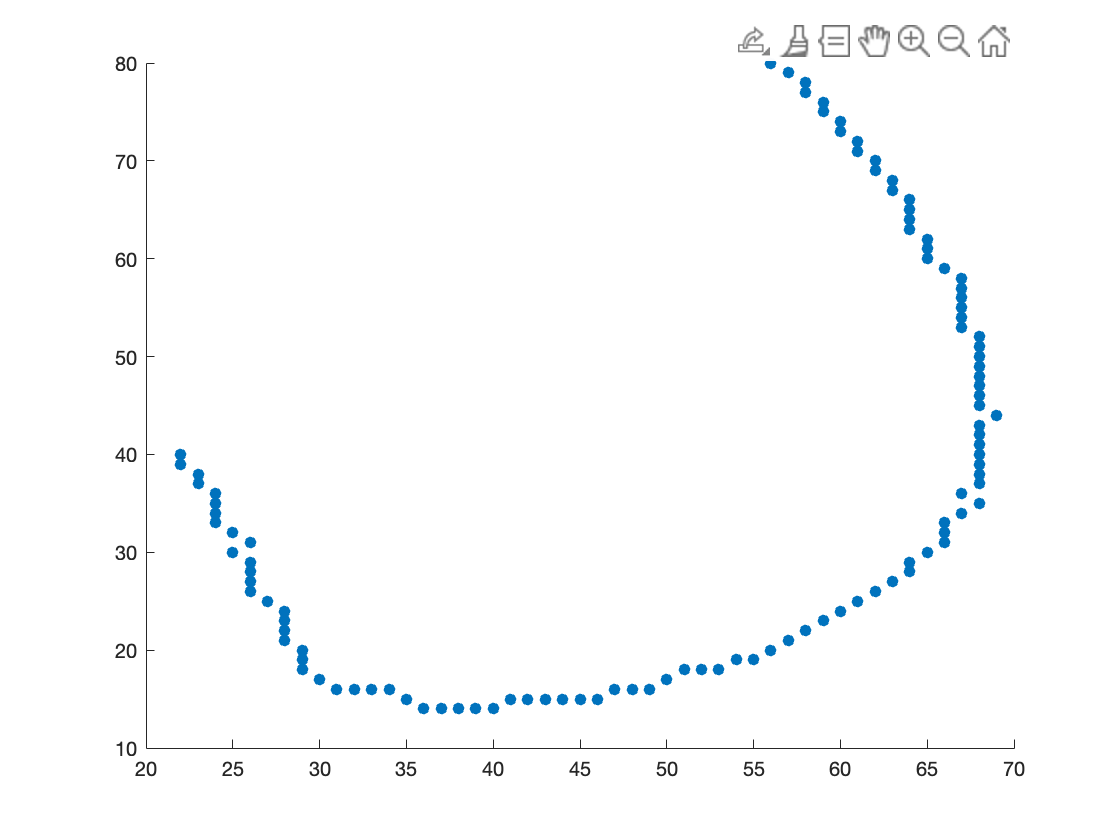

SkelCoords2=SkelYZ;
[SkelCoords2,SkelCoordsIdx] = unique(SkelCoords2,"rows","stable");
SkelCoordsfinal = (SkelCoords(SkelCoordsIdx,:));

SkelCoords2Copy = SkelCoords2; %make copy of SkelCoords2 because the values will change within the for loop
ordered = zeros(length(SkelCoords2(:,1)),1); %pre-allocate variable

figure(1)
scatter(SkelCoords2(:,1),SkelCoords2(:,2),'filled');
[yi, zi] = getpts; % select beginning (start of aortic arch) from plot
yi = round(yi);
zi = round(zi);
StartPoint = [yi zi]; %Will interactively pick this point from scatter plot (required used input)
hold off


for i = 1:length(SkelCoords2Copy(:,1))

    ForDist = sum((StartPoint - SkelCoords2).^2,2);
    DistFromStart = sqrt(ForDist); %determines distance of all points from the selected start point
    DistFromStart = DistFromStart';
    DistFromStartOrdered = sort(DistFromStart,"ascend");
    SecondSmallest = DistFromStartOrdered(2) %the next point along the path will be the 2nd shortest distance, because the 1st shortest is the start point (distance = 0)
    idxPoint = DistFromStart==SecondSmallest;
    %^^^ "idxPoint" is the next point along the path of the aorta
    if nnz(idxPoint)>1
        break
    end

    %Give prior starting points a new position that is far from all other points:
    %   Originally, when this loop iterates, it would still calculate the
    %   distance of earlier point and determine them as closest to the new
    %   point. To avoid this, I give the previous
    %   points (or start points) a distance far far away so that the
    %   next time the alogrithm iterates, it will calculate them as far away and will not select them as the shortest point:
    SkelCoords2toDelete = SkelCoords2(:,1)==StartPoint(1) & SkelCoords2(:,2)==StartPoint(2);
    SkelCoords2(SkelCoords2toDelete,:)=[1000 1000];
    ordered(idxPoint) = i;

    %Update Startpoint
    clear StartPoint
    StartPoint = [SkelCoords2(idxPoint,1) SkelCoords2(idxPoint,2)]; %defines the new start point as the current position (smallest distance from previous point)
    
    
    clear idxPoint 
    clear DistFromStart
    clear DistFromStartOrdered
end

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1

SecondSmallest = 1.4142

SecondSmallest = 1.4142

SecondSmallest = 1.3182e+03

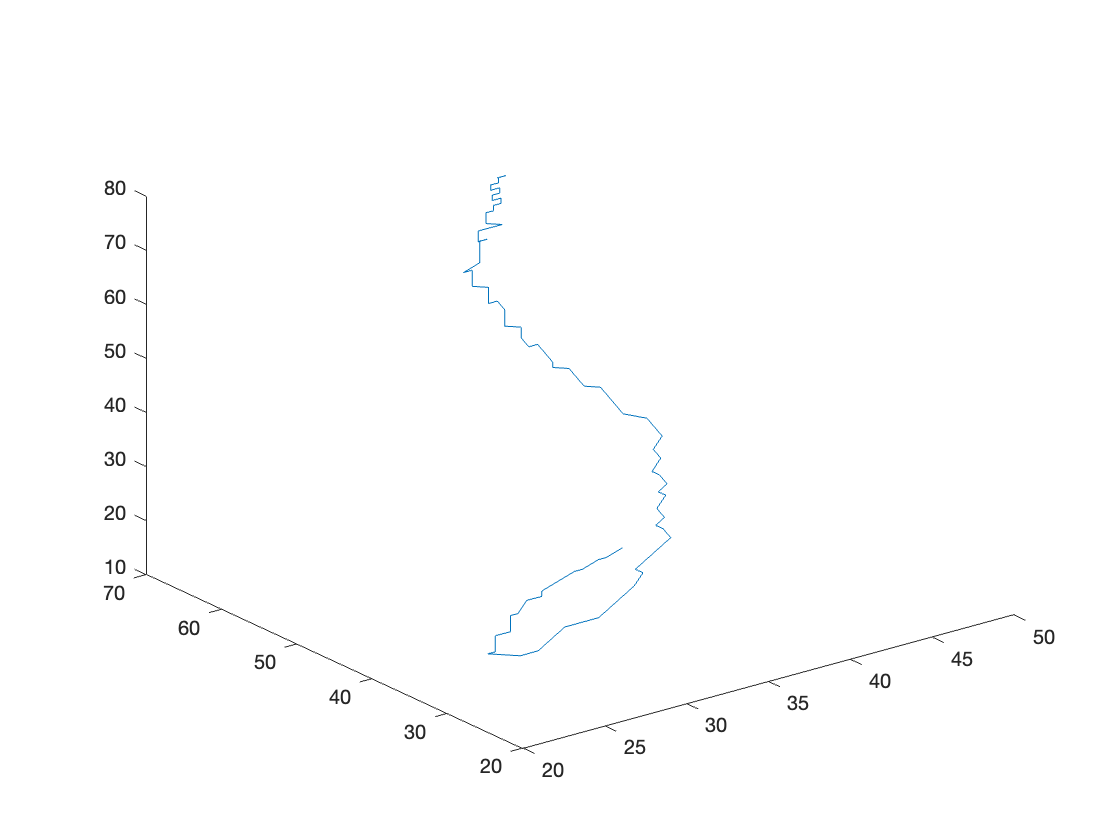


final = [SkelCoordsfinal ordered];
final = array2table(final); %convert to table variable
final = sortrows(final,"final4",'ascend'); %place in ascending order

plot3(final.final1,final.final2,final.final3);

Xfinal = final.final1;
Yfinal = final.final2;
Zfinal = final.final3;
CenterlineOrdered = [final.final1 final.final2 final.final3] %the final, ordered centerline points

CenterlineOrdered =     27    22    40
    26    22    39
    26    23    38
    25    23    37
    25    24    36
    24    24    35
    23    24    34
    23    24    33
    23    25    32
    23    26    31


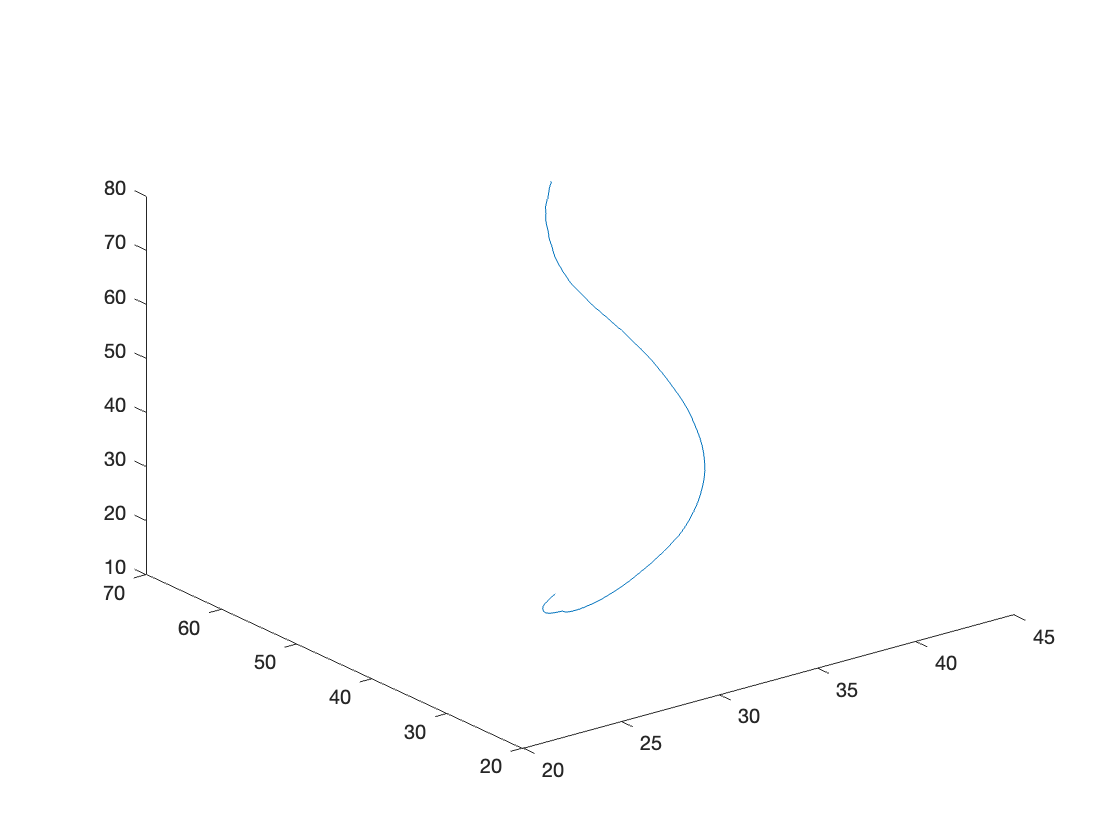


% Smooth centerline points data
CenterlineOrdered = smoothdata(CenterlineOrdered,"movmean","SmoothingFactor",0.15);
plot3(CenterlineOrdered(:,1),CenterlineOrdered(:,2),CenterlineOrdered(:,3));


%get normals for obliqueslice() function
Normals = diff(CenterlineOrdered)

Normals =    -0.0817    0.1797   -0.5000
   -0.0731    0.1608   -0.5000
   -0.0658    0.1447   -0.5000
   -0.0595    0.1786   -0.5000
   -0.0087    0.1623   -0.5000
    0.0356    0.1482   -0.5000
    0.0743    0.1775   -0.5000
    0.1083    0.2033   -0.5000
    0.1385    0.2262   -0.4615
    0.1652    0.2464   -0.4274


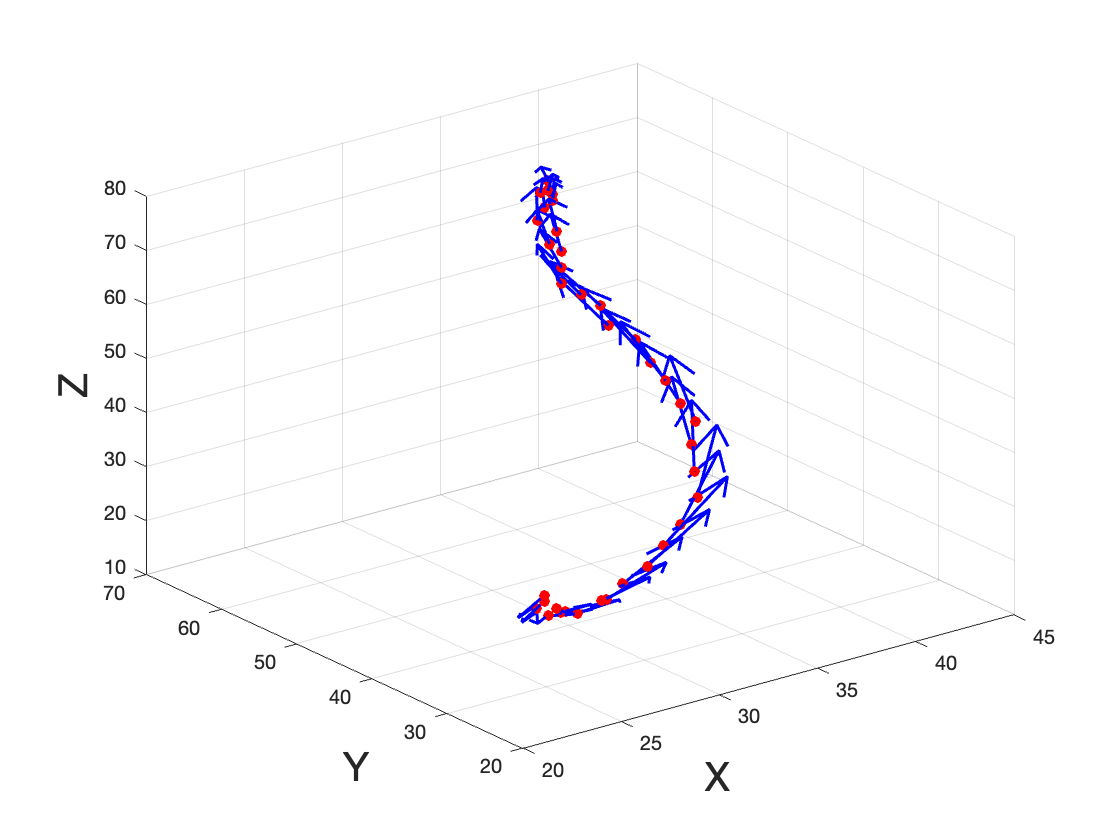


Normals = Normals(1:3:end,:); %bettwe normal vectors are obtained when skiping a few positions. Too much variablility to normal vector direction when you use each point (determined from quality control steps below)
CenterlineOrdered = CenterlineOrdered(1:3:end,:);
CenterlineOrdered = round(CenterlineOrdered(:,:));

%Create quiver plot for quanlity control step to make sure normal vectors
%look correct.
%   This section of code often has an error. If error occurs, place a "-1"
%   after "end" on each of the variables in the quiver3 and scatter3 plots.
%   for example, you will have to place "1:end-1" in the x position in the
%   following 6 locations below... Not sure why this is, but it something
%   that needs to be solved moving forward. It likely is due to skipping
%   positions when determining normal vectors and depends on whether there
%   is even or odd number of points.
quiver3(CenterlineOrdered(1:end,1),CenterlineOrdered(1:end,2),CenterlineOrdered(1:end,3),Normals(:,1),Normals(:,2),Normals(:,3),'LineWidth',1.5,'Color','blue');
xlabel("X","FontSize",20)
ylabel("Y","FontSize",20)
zlabel("Z","FontSize",20)
hold on
scatter3(CenterlineOrdered(1:end,1),CenterlineOrdered(1:end,2),CenterlineOrdered(1:end,3),30,'red','filled');
hold off

## Find Oblique Slices using Centerline and Normal Vectors and Calculate Metric

Normals = [Normals(:,2) Normals(:,1) Normals(:,3)]; %for following functions to work, normals and positions had to be placed in y,x,z order
CenterlineOrdered = [CenterlineOrdered(:,2),CenterlineOrdered(:,1),CenterlineOrdered(:,3)]

CenterlineOrdered =     25    23    32
    25    23    31
    26    23    29
    26    24    28
    27    24    26
    28    25    25
    30    26    23
    31    27    21
    33    29    20
    35    30    18


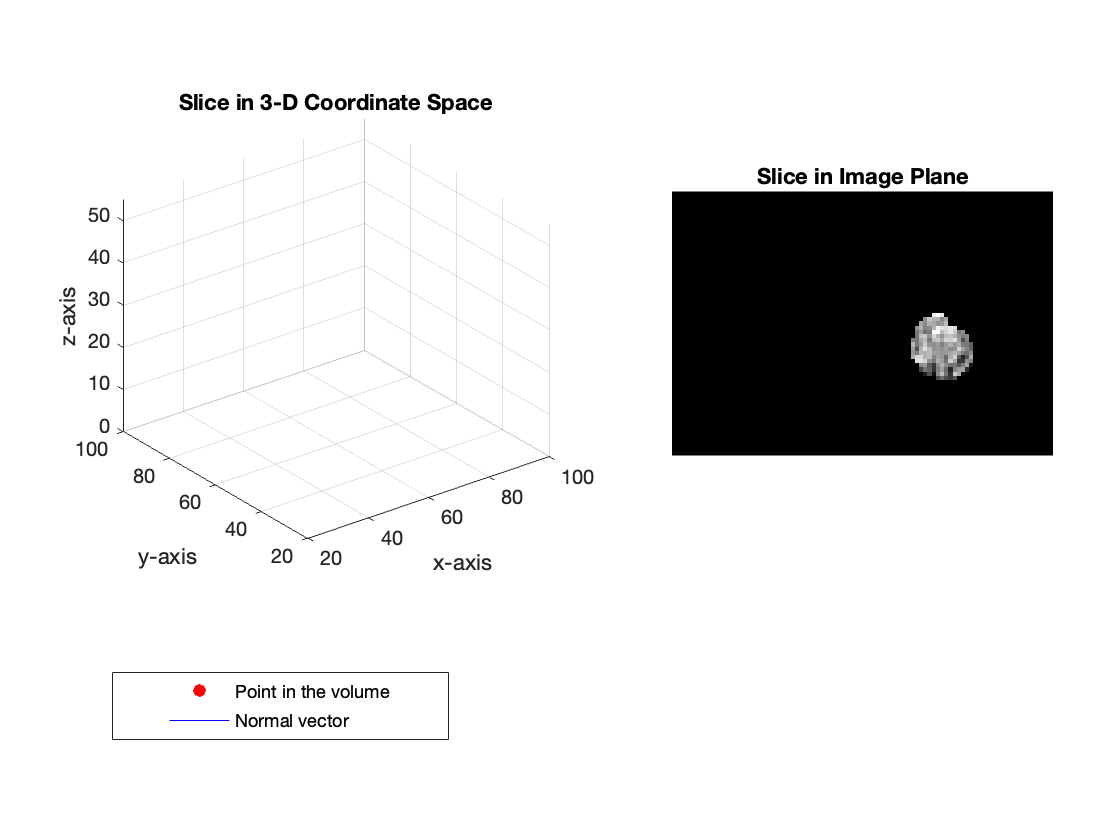

Cell1 = cell(length(CenterlineOrdered),1);

%figure(2)
for s = 1:(length(CenterlineOrdered(:,1))-1)
    pt = CenterlineOrdered(s,:);
    normal = Normals(s,:);
    [B,x,y,z] = obliqueslice(img3DRaw(:,:,:,1),pt,normal,"Method","linear","OutputSize","full","FillValues",0);
    [Bpet,xpet,ypet,zpet] = obliqueslice(img3DRaw(:,:,:,2),pt,normal,"Method","linear","OutputSize","full","FillValues",0);
    
    %Bslices(:,:,s) = B;

    %Get only the data around the point
    xround = round(x(:,:));
    yround = round(y(:,:));
    zround = round(z(:,:));
    %IDX = find(x==pt(1));
    IDX = yround==pt(2) & zround==pt(3) & xround==pt(1);
    
    %make sure it finds a point
    num = nnz(yround==pt(2) & zround==pt(3) & xround==pt(1));
    if num == 0
        IDX = yround==(pt(2)+1) & zround==pt(3) & xround==pt(1);
    end
    num = nnz(IDX);
    if num == 0
        IDX = yround==(pt(2)-1) & zround==pt(3) & xround==pt(1);  
    end

    [IDXrow,IDXcol] = find(IDX);
    IDXroww(s) = IDXrow(1);
    IDXcoll(s) = IDXcol(1);
    
    %B is the plane determined by oblique slice. The following code sets
    %   every point (voxel) outside of an 11x11 box around the center point as NaN.
    %   This was necessary because if this is not done, voxels from the
    %   other side (ascending or descending) aorta would be included. The
    %   11x11 size can likely be changed or expanded, but must do quality
    %   control step to make sure the other side of the aorta was not
    %   included.
    B([1:(IDXroww(s)-11) (IDXroww(s)+11):end],:) = NaN;
    B(:,[1:(IDXcoll(s)-11) (IDXcoll(s)+11):end]) = NaN;
    Bpet([1:(IDXroww(s)-11) (IDXroww(s)+11):end],:) = NaN;
    Bpet(:,[1:(IDXcoll(s)-11) (IDXcoll(s)+11):end]) = NaN;
    %Logg = B((IDXroww(s)-10):(IDXroww(s)+10),(IDXcoll(s)-10):(IDXcoll(s)+10)) >0;

    %CALCULATE CT metrics. Some of these are exploratory...
    %find volume over 100 HU:
    vol200CTAorta(s) = nnz(B(:,:)>200)*voxelvolume; %CAC (similar to CAC Score)
    %Relative volume (aka percentage of lumen occupied by
    %macro-calcification):
    volumeOfSlice(s) = nnz(B(:,:)>0)*voxelvolume;
    RelativeMacroVolume(s) = vol200CTAorta(s)/volumeOfSlice(s);
    %find mean HU of perp slice
    meanArchCT(s) = mean(B(:,:),'all','omitnan');
    maxArchCT(s) = max(B(:,:),[],'all');
   
    Cell1{s,1} = Bpet(:);
    %CALCULATE PET metrics:
    maxArchPET(s) = max(Bpet(:,:),[],'all');
    volAbove2SUV = nnz(Bpet(:,:)>2)*voxelvolume;
    IDXpetAorta = Bpet(:,:)>2;
    MeanSUVAorta1 = mean(Bpet(IDXpetAorta),'all','omitnan');
    IDXisNan = isnan(MeanSUVAorta1);
    MeanSUVAorta1(IDXisNan)=1; %set equal to 1 (background)
    MeanSUVAorta(s) = MeanSUVAorta1;
    %get mean of 90th percentile
    BpetSorted = rmmissing(sort(Bpet(:),'descend'));
    NintiethPrcentile = prctile(BpetSorted(:),90);
    idxAbove90th = BpetSorted>NintiethPrcentile;
    Mean90th(s) = mean(BpetSorted(idxAbove90th)); % THIS IS THE mCS

    %Total lesion activity (or also often caled total lesion glycolysis in
    %   FDG PET) is likely a good measure... It is defined as volume of lesion above some threshold, 
    %   multipled by the mean SUV of those voxels. This is exploratory for future work
    %TLAAorta(s) = MeanSUVAorta1.*volAbove2SUV;

    % Display the slice in 3-D coordinate space:
    subplot('Position',[0.11 0.36 0.38 0.5])
    surf(x,y,z,B,'EdgeColor','None','HandleVisibility','off');
    grid on 
    %view([-24 12])
    colormap("hot")
    xlabel('x-axis');
    ylabel('y-axis');
    zlabel('z-axis');
    zlim([0 55]);
    ylim([20 100]);
    xlim([20 100]);
    title('Slice in 3-D Coordinate Space') 
    % Plot the point and the normal vector.
    hold on
    plot3(pt(1),pt(2),pt(3),'or','MarkerFaceColor','r')
    plot3( ...
        pt(1)+[-normal(1) normal(1)], ...
        pt(2)+[-normal(2) normal(2)], ...
        pt(3)+[-normal(3) normal(3)], ...
        '-b','MarkerFaceColor','b')
    legend('Point in the volume','Normal vector','Position',[0.1 0.12 0.3 0.08])
    hold off   
    % Display the extracted slice.
    subplot('Position',[0.6 0.37 0.34 0.49])
    imshow(B,[])
    title('Slice in Image Plane')
    pause(0.15);  
end    

### Find When direction of midline changes... to find "peak" of Aorta (where deltaZ = 0) then split into ascending and descending Aorta

% The point where the ascending aorta becomes the descending aorta is
% technically where the tangent of the centerline is equal to 0

DiffZ = diff(CenterlineOrdered(:,3));
findZeros = find(DiffZ==0);
FindMidpoint = median(findZeros); %there may be multiple points where this tangent is = 0, so just use the median

% Make variable containing metric for asending aorta
AscendingAortaCTmean = meanArchCT(1:FindMidpoint);
AscendingAortaCTvolume = vol200CTAorta(1:FindMidpoint); % calcific volume
AscendingAortaPETmean = MeanSUVAorta(1:FindMidpoint);
AscendingAortaPETmax = maxArchPET(1:FindMidpoint);
AscendingAortaPETmean90th = Mean90th(1:FindMidpoint); % This is the mCS

% Make variable containing metric for descending aorta
DescendingAortaCTmean = meanArchCT(FindMidpoint+1:end);
DescendingAortaCTvolume = vol200CTAorta(FindMidpoint+1:end);
DescendingAortaPETmean = MeanSUVAorta(FindMidpoint+1:end);
DescendingAortaPETmax = maxArchPET(FindMidpoint+1:end);
DescendingAortaPETmean90th = Mean90th(FindMidpoint+1:end);

%vertically concatenate
AscendDescendCTmean = [AscendingAortaCTmean';DescendingAortaCTmean'];
AscendDescendCTvolume = [AscendingAortaCTvolume';DescendingAortaCTvolume'];
AscendDescendPETmean = [AscendingAortaPETmean';DescendingAortaPETmean'];
AscendDescendPETmax = [AscendingAortaPETmax';DescendingAortaPETmax'];
AscendDescendPETmean90th = [AscendingAortaPETmean90th';DescendingAortaPETmean90th'];

% ^^ This are the variables containing the calculated metrics and are in
%   order from the beginning of the aorta to the end of descending aorta.
%   This will be used later in the code

## Separate CT and PET data Based on Vasculature Segments

% Now, the following code will seperate the segments below the aortic arch
% for handling.

%Make table with only data within Abdominal Aorta Segment
idxAbdominal = VascularCT.VoxelZ >= AbdominalBegin & VascularCT.VoxelZ <= (IliacBegin-1);
VascularCTAbd = VascularCT(idxAbdominal,:);
VascularPETAbd = VascularPET(idxAbdominal,:);

%Make table with only data within Iliac Arterie Segment
idxIliac = VascularCT.VoxelZ >= IliacBegin & VascularCT.VoxelZ <= (FemoralBegin-1);
VascularCTIliac = VascularCT(idxIliac,:);
VascularPETIliac = VascularPET(idxIliac,:);

%Make table with only data within Femoral Artery Segment
idxFemoral = VascularCT.VoxelZ >= FemoralBegin & VascularCT.VoxelZ <= (PopBegin-1);
VascularCTFemoral = VascularCT(idxFemoral,:);
VascularPETFemoral = VascularPET(idxFemoral,:);

%Make table with only data within Popliteal Artery Segment
idxPop = VascularCT.VoxelZ >= PopBegin & VascularCT.VoxelZ <= (PostTibBegin-1);
VascularCTPop = VascularCT(idxPop,:);
VascularPETPop = VascularPET(idxPop,:);

%Make table with only data within Posterial Tib Artery Segment
idxPostTib = VascularCT.VoxelZ >= PostTibBegin & VascularCT.VoxelZ <= ending;
VascularCTPostTib = VascularCT(idxPostTib,:);
VascularPETPostTib = VascularPET(idxPostTib,:);

## Adjust Z-slice to Proportion (%) from Beginning of Vascular Segment, and Place on Continous Axis

% The following code calculates the standardized vascular atlas (SVA) positions
% by first giving each slice a percentage distance away from the beginning
% of its respective slice, then scaling it by the segment scaling factors

% First make vector the length of number of points (perpendicular slices) throughout the volume, then
%transform into a percentage from the beginning
AscendArray = 1:numel(AscendingAortaPETmean);
xAscend = (AscendArray-AscendArray(1)+1)./numel(AscendingAortaPETmean);
% Multiply by scaling factor of ascending arch
xAscendCont = xAscend*SFAscend;

DescendArray = 1:numel(DescendingAortaPETmean);
xDescend = (DescendArray-DescendArray(1)+1)./numel(DescendingAortaPETmean);
xDescend = xDescend*SFDescend;
% Must add the last SVA position of the ascending aorta to the descending
% aorta position so they are on a continuous axis:
xDescendCont = xDescend + xAscend(end);

% For abdominal aorta:
xAbdominal = (VascularCTAbd.VoxelZ - VascularCTAbd.VoxelZ(1)+1)./(VascularCTAbd.VoxelZ(end)-VascularCTAbd.VoxelZ(1));
xAbdominal = xAbdominal*SFAbdominal;
xAbdominalCont = xAbdominal + xDescendCont(end); %Adjust to continuous axis;
% Go ahead and add the x position and SVA position as column variables to
% the original, segmented voxel-level data:
VascularCTAbd = addvars(VascularCTAbd,xAbdominal,'After',"HU");
VascularPETAbd = addvars(VascularPETAbd,xAbdominal,'After',"SUV");
VascularCTAbd = addvars(VascularCTAbd,xAbdominalCont,'After',"HU");
VascularPETAbd = addvars(VascularPETAbd,xAbdominalCont,'After',"SUV");

% For iliac arteries:
xIliac = (VascularCTIliac.VoxelZ - VascularCTIliac.VoxelZ(1)+1)./(VascularCTIliac.VoxelZ(end)-VascularCTIliac.VoxelZ(1));
xIliac = xIliac*SFIliac;
xIliacCont = xIliac + xAbdominalCont(end);
VascularCTIliac = addvars(VascularCTIliac,xIliac,'After',"HU");
VascularPETIliac = addvars(VascularPETIliac,xIliac,'After',"SUV");
VascularCTIliac = addvars(VascularCTIliac,xIliacCont,'After',"HU");
VascularPETIliac = addvars(VascularPETIliac,xIliacCont,'After',"SUV");

% For femoral arteries:
xFemoral = (VascularCTFemoral.VoxelZ - VascularCTFemoral.VoxelZ(1)+1)./(VascularCTFemoral.VoxelZ(end)-VascularCTFemoral.VoxelZ(1));
xFemoral = xFemoral*SFFemoral;
xFemoralCont = xFemoral + xIliacCont(end);
VascularCTFemoral = addvars(VascularCTFemoral,xFemoral,'After',"HU");
VascularPETFemoral = addvars(VascularPETFemoral,xFemoral,'After',"SUV");
VascularCTFemoral = addvars(VascularCTFemoral,xFemoralCont,'After',"HU");
VascularPETFemoral = addvars(VascularPETFemoral,xFemoralCont,'After',"SUV");

% For popliteal arteries:
xPop = (VascularCTPop.VoxelZ - VascularCTPop.VoxelZ(1)+1)./(VascularCTPop.VoxelZ(end)-VascularCTPop.VoxelZ(1));
xPop = xPop*SFPop;
xPopCont = xPop + xFemoralCont(end);
VascularCTPop = addvars(VascularCTPop,xPop,'After',"HU");
VascularPETPop = addvars(VascularPETPop,xPop,'After',"SUV");
VascularCTPop = addvars(VascularCTPop,xPopCont,'After',"HU");
VascularPETPop = addvars(VascularPETPop,xPopCont,'After',"SUV");


## Combine Vascular Segments into 1 Table and Cleanup 

VascularCT = [VascularCTAbd{:,:};VascularCTIliac{:,:};VascularCTFemoral{:,:};VascularCTPop{:,:}];
VascularCT(:,[1 2]) = [];
VascularCT = array2table(VascularCT,"VariableNames",["OriginalZSlice" "HU" "XAxisContinuous" "XAxis"]);
VascularCT = movevars(VascularCT,"HU","After","XAxis");
VascularCT = movevars(VascularCT,"XAxis","Before","XAxisContinuous");

VascularPET = [VascularPETAbd{:,:};VascularPETIliac{:,:};VascularPETFemoral{:,:};VascularPETPop{:,:}];
VascularPET(:,[1 2]) = [];
VascularPET = array2table(VascularPET,"VariableNames",["OriginalZSlice" "SUV" "XAxisContinuous" "XAxis"]);
VascularPET = movevars(VascularPET,"SUV","After","XAxis");
VascularPET = movevars(VascularPET,"XAxis","Before","XAxisContinuous");

%Add the PET data to combine info
VascularPETCT = VascularCT;
VascularPETSUV = VascularPET.SUV(:);
VascularPETCT = addvars(VascularPETCT,VascularPETSUV,'After',"HU");

## Get Slice-Wise Data (Mean, Max, Median, SD, etc.) for Axial Slices

uniqX = unique(VascularPETCT.XAxisContinuous,"rows"); %get unique SVA positions
xAxialsCont = uniqX;
P = zeros(numel(uniqX),2); %pre-allocate variable to populate
Cell2 = cell(numel(uniqX),1);

% Calculate metrics (most importantly mCS) for each unique SVA position:
for k = 1:numel(uniqX)
    contValue = uniqX(k);

    IdxValues2get = VascularPETCT.XAxisContinuous == uniqX(k);
    CTValues2get = VascularPETCT.HU(IdxValues2get);
    PETValues2get = VascularPETCT.VascularPETSUV(IdxValues2get);
    Cell2{k,1} = PETValues2get;
    meanCTslice = mean(CTValues2get);
    %meanPETslice = mean(PETValues2get);%BackgroundSUV;
    maxPETaxial = max(PETValues2get);

    vol200CTVascular = nnz(CTValues2get>200)*voxelvolume;
    %get relative volume (%volume per slice occupies by calcification
    VolumeCTSlice = nnz(CTValues2get(:,:)>0)*voxelvolume;
    RelativeMacroVolumeAxial = vol200CTVascular/VolumeCTSlice;

    volAbove2SUV = nnz(PETValues2get>2)*voxelvolume;
    IDXpetVascular = PETValues2get>2;
    MeanSUVVascular = mean(PETValues2get(IDXpetVascular),'all','omitnan');
    IDXisNan = isnan(MeanSUVVascular);
    MeanSUVVascular(IDXisNan)=1;%1 = background (background/background)
    TLAVascular = MeanSUVVascular.*volAbove2SUV;
    
    %get mean of 90th percentile. THIS IS mCS
    PETSorted = rmmissing(sort(PETValues2get,'descend'));
    Prcentile90 = prctile(PETSorted(:),90);
    idxAbove90 = PETSorted>=Prcentile90;
    Mean90 = mean(PETSorted(idxAbove90));

    P(k,[1 2 3 4 5]) = [meanCTslice vol200CTVascular MeanSUVVascular maxPETaxial Mean90];
end

Cell = [Cell1;Cell2]';
%boxplot(Cell)
VoxelValuesPerSlice = NaN*ones(20000,length(Cell));
for j = 1:length(Cell)
    GET = Cell{1,j};
    VoxelValuesPerSlice(1:length(GET),j) = GET;
end
VoxelValuesPerSlice = sort(VoxelValuesPerSlice,1,"ascend");
%VoxelsPerSlice = 
%box(VoxelValuesPerSlice)

%Axials is table with all SVA positions and the calculated metrics for all
%   slices below the aortic arch:
Axials = [xAxialsCont P(:,1) P(:,2) P(:,3) P(:,4) P(:,5)];

## Prepare Ascending and Descending Aorta Data and Combine with Axial data (from below aortic arch):

%Put in array where Columns are: [xcontinuous   MeanCT   MeanSUV>2background  maxPET]
xContAscendDescend = [xAscendCont';xDescendCont'];
AscendDescend = [xContAscendDescend AscendDescendCTmean AscendDescendCTvolume AscendDescendPETmean AscendDescendPETmax AscendDescendPETmean90th];

% Combine Arch and Axials (Axials is just the data below the aortic arch,
% where perpendicual slices were not used)
CombinedArchAxials = [AscendDescend;Axials];

## Prepare Patient Data for Export

%preallocate
Segment = strings(numel(CombinedArchAxials(:,1)),1);

%Add coliums that has the vascular segment!
%First find the indices that relate to the vascular segments by using the continous x-axis values
IdxAscend = find(CombinedArchAxials(:,1) <= xAscendCont(end));
IdxDescend = find(CombinedArchAxials(:,1) > xAscendCont(end) & CombinedArchAxials(:,1) <= xDescendCont(end));
IdxAbdominal = find(CombinedArchAxials(:,1) > xDescendCont(end) & CombinedArchAxials(:,1) <= xAbdominalCont(end));
IdxIliacs = find(CombinedArchAxials(:,1) > xAbdominalCont(end) & CombinedArchAxials(:,1) <= xIliacCont(end));
IdxFemoral = find(CombinedArchAxials(:,1) > xIliacCont(end) & CombinedArchAxials(:,1) <= xFemoralCont(end));
IdxPop = find(CombinedArchAxials(:,1) > xFemoralCont(end) & CombinedArchAxials(:,1) <= xPopCont(end));
%IdxPostTib = find(CombinedArchAxials(:,1) > xPopCont(end) & CombinedArchAxials(:,1) <= xPostTibCont(end))

Segment(IdxAscend) = 'Ascending';
Segment(IdxDescend) = 'Descending';
Segment(IdxAbdominal) = 'Abdominal';
Segment(IdxIliacs) = 'Iliac';
Segment(IdxFemoral) = 'Femoral';
Segment(IdxPop) = 'Popliteal';
%Segment(IdxPostTib) = 'Posterior Tibials';

Combined = array2table(CombinedArchAxials,"VariableNames",{'Continous Axis (Atlas)', 'MeanHU', 'Volume (CACS)','meanSUV>2Background' ,'maxSUV','Mean90th'});
Combined = addvars(Combined,Segment,'Before','Continous Axis (Atlas)');

## Plot CT and PET Data to View Patient's Active and Stable Calcification

%%This figure is not formated. Currently using GraphPad Prism to visualize

%figure
%plot(AscendDescend(:,1),AscendDescend(:,3),"b-","LineWidth",1)
%hold on
%plot(Axials(:,1),Axials(:,3),"b-","LineWidth",1);
%yyaxis left
%xlabel("Vacular Atlas","FontSize",14,"FontWeight","bold")
%ylabel("HU","FontSize",14,"FontWeight","bold","Color","b")
%set(gca,'ycolor','b')
%ylim([0 150])
%xlim([0 1200])
%yyaxis right
%plot(AscendDescend(:,1),AscendDescend(:,5),"r-","LineWidth",1)
%hold on
%plot(Axials(:,1),Axials(:,5),"r-","LineWidth",1);
%ylim([0 5]);
%yaxis('')
%ylabel("SUVmean","FontSize",14,"FontWeight","bold","Color","r")
%set(gca,'ycolor','r')
%ylim([0 150]);
%xline(93,'k--',"LineWidth",1.5); % Place holder for the end x value for aorta
%xline(xAscendCont(end),'k--',"LineWidth",1.5);
%xline(xDescendCont(end),'k--',"LineWidth",1.5);
%xline(VascularCTAbd.xAbdominalCont(end),'k--',"LineWidth",1.5);
%xline(VascularCTIliac.xIliacCont(end),'k--',"LineWidth",1.5);
%xline(VascularCTFemoral.xFemoralCont(end),'k--',"LineWidth",1.5);
%xline(VascularCTPop.xPopCont(end),'k--',"LineWidth",1.5)
%box off


writetable(Combined,'...','WriteMode','overwrite');
